# Cascadia

Resources

- [Better Dates for Cascadia Quakes](https://eos.org/science-updates/swipe-left-on-the-big-one-better-dates-for-cascadia-quakes)

## Read and clean the raw data

clearvars
withwarnoff('MATLAB:table:ModifiedAndSavedVarnames');

% Read the data
cascadia = readtable('cascadia.xlsx');
varnames = string(unique(cascadia.Var2));

% Convert the date labels to categorical
datelabels = categorical(cascadia.Year1);
datelabels = rmmissing(datelabels);

chunksize = numel(varnames);
eventdata = cell(height(cascadia)/chunksize, 1);
for n = 1:height(cascadia)/chunksize
   [chunkstart, chunkend] = chunkLoopInds(n,1,chunksize);
   chunkdata = cascadia{chunkstart:chunkend, vartype("numeric")};
   eventdata{n} = transpose(chunkdata(~isnan(chunkdata)));
end
eventdata = vertcat(eventdata{:});

% The "Year" variable is missing for all events
varnames = varnames(1:end-1);

Data = array2table(eventdata, "VariableNames", varnames);
Data.Label = datelabels;

% Adjust the "Mean Age" to be relative to this year
thisyear = year(datetime("now"));
ireference = find(contains(string(Data.Label), "AD"));
refyears = str2double(replace(string(Data.Label(ireference)), "AD", ""));
offset = thisyear - Data.("Mean age")(ireference) - refyears;
Data.("Mean age") = Data.("Mean age") + offset(1);

% Add datetime dates
Data.Date = datetime(thisyear, 1, 1) - years(Data.("Mean age"));
Data.Year = year(Data.Date);

% Sort by age
Data = sortrows(Data, "Date", "ascend");

## Explore the data

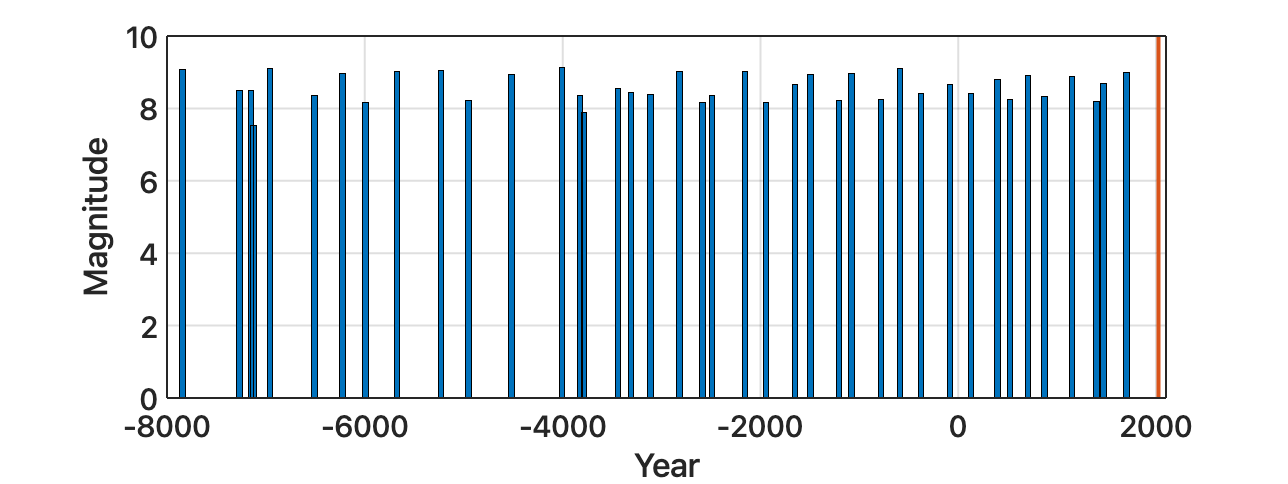

ans =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2023 2023]
              YData: [0 10]

  Show all properties

figure('Position', [0 0 800 300])
bar(Data.Year, Data.Magnitude, 2);
xlabel('Year');
ylabel('Magnitude')
set(gca, 'TickLength', [0 0], 'XLim', [-8000 2100])
vertline(thisyear)

The chart shows all 40 major earthquakes in the Cascadia Subduction Zone that geologists estimate have occurred since 9845 B.C. Scientists estimated the magnitude and timing of each quake by examining soil samples at more than 50 undersea sites between Washington, Oregon and California.

Data.period = [NaN; diff(Data.Year)];
summary(Data(:, "period"))

Variables:
    period: 40×1 double
        Values:
            Min             27    
            Median          231   
            Max             577   
            NumMissing      1     


yearsBetweenQuakes = diff(Data.Year);
avgYearsBetweenQuakes = mean(yearsBetweenQuakes);
stdvYearsBetweenQuakes = std(yearsBetweenQuakes);
medianYearsBetweenQuakes = median(yearsBetweenQuakes);
iqrYearsBetweenQuakes = iqr(yearsBetweenQuakes);

Display the mean plus or minus standard deviation and median plus or minus interquartile range

[avgYearsBetweenQuakes avgYearsBetweenQuakes+stdvYearsBetweenQuakes*[-1 1]]

ans =   244.7179  122.3034  367.1325


[medianYearsBetweenQuakes medianYearsBetweenQuakes+iqrYearsBetweenQuakes*[-1 1]]

ans =   231.0000  104.2500  357.7500


## Years overdue

Find how long it's been since the most recent quake

mostRecentQuake = Data.Year(end)

mostRecentQuake = 1699

timeSinceMostRecentQuake = thisyear - mostRecentQuake

timeSinceMostRecentQuake = 324

Compare that to the average, median, and variation of years between quakes

yearsOverdue = timeSinceMostRecentQuake - medianYearsBetweenQuakes

yearsOverdue = 93